## MA 402 Project 2

### Monday May 2, 2022

### Andrea Stancescu, Jenna Varnell, Omry Bewster

% Andrea Stancescu, Jenna Varnell, Omry Brewster
% MA 402 Project 2 
% 5-2-2022
% MATLAB .mlx file with integrated text and code

### 1. Introduction

In this project we will conduct an in depth analysis of the jokesSp22 data sets. This .mat file contains measured data about percieved comedy level of 42 jokes. Data collected over multiple past semesters will be finally used to predict a linear least squares model which we will ultimately test on a testing set consisting of data collected from our peers. 

The concepts and methods employed in this project include principal component analysis (PCA), correlation and covariance, kmeans clustering, and the least squares method. All methods and techniques will be described below as well as any results and conclusions drawn. 

### 2. Preliminaries - Data Exploration 

We start with loading the joke data which contains 4 items:

1) JTrain, a matrix of size 63 × 42 containing ratings of 42 jokes from 63 students over past semesters. Jokes were rated on a scale of 0 (not funny) to 10 (hilarious). Not all entries of JTrain are integers since the professor took the liberty of filling in some missing entries.

2) jokes, a cell array of length 42 containing a one-word descriptor for each joke.

3) jokeTexts, a cell array of length 42 containing the full text of each joke.

4) JTest, a matrix of size 36×20 containing ratings from this semester’s students of the first 20 jokes in the survey. Responses for the remaining 22 jokes are withheld by the professor.

load jokesSp22.mat

(a) First we will find the jokes with the highest and lowest ratings over JTrain. We do this by finding the mean of each column in JTrain and finding the maximum and minimum of this resulting vector of averages.  

% a) Find the jokes with the highest and lowest ratings over JTrain.
% aka find the mean of each column (joke) and find smallest and largest average / mean 
 avg = mean(JTrain,1);
% return 42 length vector with the mean score of each columns / joke 
[score_f, funniest] = max(avg);
fprintf("The funniest joke is the %s joke which says ''%s'' \n", char(jokes(funniest)), char(jokeTexts(funniest)))

The funniest joke is the Hotel joke which says ''An engineer, a physicist and a mathematician are sleeping in a room. There is a fire in the room. The engineer wakes up, sees the fire, picks up the bucket of water and douses the fire and goes back to sleep.   Again there is fire in the room. This time, the physicist wakes up, notices the bucket, fills it with water, calculates the optimal trajectory and douses the fire in minimum amount of water and goes back to sleep.  Again there is fire. This time the mathematician wakes up.  He looks at the fire, looks at the bucket and the water and exclaims, "A solution exists" and goes back to sleep.'' 


[score_l, nonfunny] = min(avg);
fprintf("The least funny joke is the %s joke which says ''%s'' \n", char(jokes(nonfunny)), char(jokeTexts(nonfunny)))

The least funny joke is the Rabbit joke which says ''Two cows are in a field. Suddenly, from behind a bush, a rabbit leaps out and runs away. One cow looks around a bit, eats some grass, and then wanders off. '' 


(b) Next we will find the person that gave the highest average rating on the jokes. We do this by finding the row-wise mean of JTrain. We are also finding the jokes that this specific person disliked the most. We do this by finding the minimum(s) in the row that corresponds with the student we just found. 

person = mean(JTrain, 2);
% return a 63 x 1 length vector with mean score of each individual
[score_p, highestperson] = max(person);
fprintf("The individual who gave the highest average joke rating is the %d person with an avergae joke rating of %f \n", highestperson , score_p)

The individual who gave the highest average joke rating is the 11 person with an avergae joke rating of 8.000000 


% find which joke the 11th person liked the least
person_data = JTrain(11,:);
overallworst_score = min(person_data);
[worst_scores, worst_jokes] = find(person_data == overallworst_score);
fprintf("The individual who gave the highest average joke rating gave two low ratings of %d. \nThe jokes that recieved these ratings were: \nthe %s joke which says ''%s'' \nand \nthe %s joke which says ''%s'' \n ", overallworst_score, char(jokes(worst_jokes(1))), char(jokeTexts(worst_jokes(1))), char(jokes(worst_jokes(2))), char(jokeTexts(worst_jokes(2))))  

The individual who gave the highest average joke rating gave two low ratings of 6. 
The jokes that recieved these ratings were: 
the Holmes joke which says ''Sherlock Holmes and Dr. Watson go on a camping trip, set up their tent, and fall asleep. Some hours later, Holmes wakes his faithful friend. "Watson, look up at the sky and tell me what you see." Watson replies, "I see millions of stars." "What does that tell you?" Watson ponders for a minute. "Astronomically speaking, it tells me that there are millions of galaxies and potentially billions of planets. Astrologically, it tells me that Saturn is in Leo. Timewise, it appears to be approximately a quarter past three. Meteorologically, it seems we will have a beautiful day tomorrow. What does it tell you?" Holmes is silent for a moment, then speaks. "Watson, you idiot, someone has stolen our tent."'' 
and 
the Ball joke which says ''A mathematician, physicist, and engineer are asked to measure the volume of a red rubber ball. The math

(c) We will use the function pcolor() in matlab and the colorbar option to get a quick view of the entire data set. The pcolor() function in MATLAB creates a pseudocolor plot using the values in matrix C. A pseudocolor plot displays matrix data as an array of colored cells (known as faces). MATLAB creates this plot as a flat surface in the x-y plane as seen below. 

Find at least one person who did not appear to take their joke-rating duties seriously, and make a histogram of their ratings.

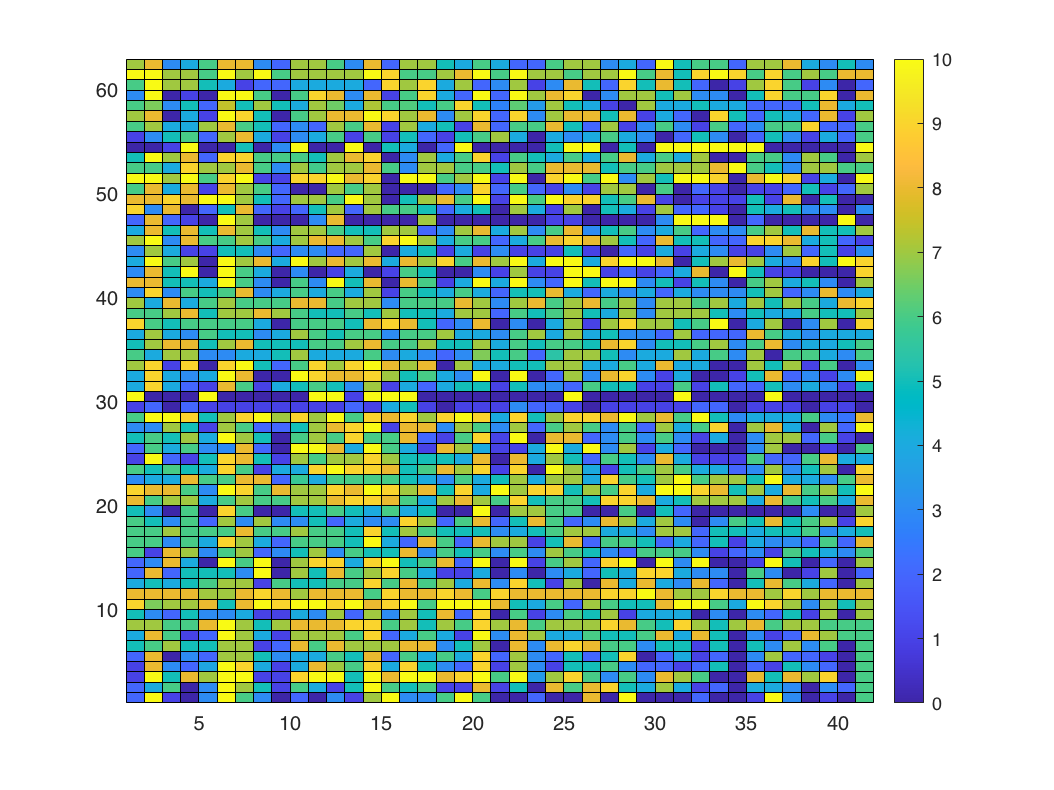


figure(1)
pcolor(JTrain)
colorbar

                                Figure 1: pseudocolor plot for the ratings in JTrain

The color bar shows that deep blue corresponds to a rating of 0 (not at all funny) whereas bright yellow corresponds to a rating of 10 (very funny)

By clicking on the colored cells, it can be seen that individual 30 did not seem to take it seriously as they rated nearly all of the jokes with very low scores (which can be seen by a row shaded nearly entirely dark blue). When examining the scores that individual 30 gave it can be seen that they only rated jokes 10, 0, or 1 showing that they did not take the time to read and consider each joke. 

The pcolor plot below shows that individual 30 rated jokes with only extreme answers (0 or 10) suggesting lack of consideration.

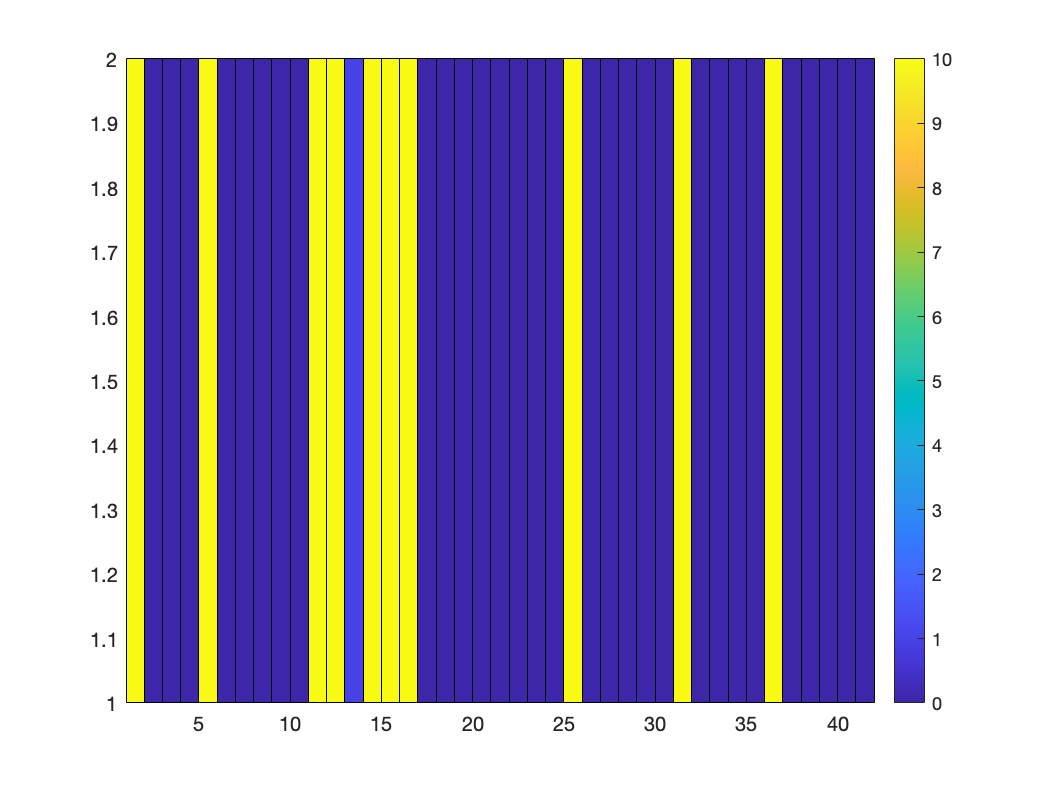

figure(2)
individ30 = JTrain(30,:);
emptyrow = zeros(1,42);
pcolor([individ30 ; emptyrow])
colorbar

                             Figure 2: pseudocolor plot for the ratings of individual 30

Individual 11 did not seem to take it seriously either as they rated nearly all of the jokes with very high scores (as can be seen by a row shaded nearly entirely yellow). When examining the scores that inidivudal 11 gave it can be seen that they only rated jokes 7, 8, 9, 10 which suggests that they might have just given every joke a high score regardless of its true comedy value.

The pcolor plot below shows nearly all questions are yellow or light green suggesting a lack of thoughtfulness. 

figure(3)

                          Figure 3: pseudocolor plot for the ratings of individual 11

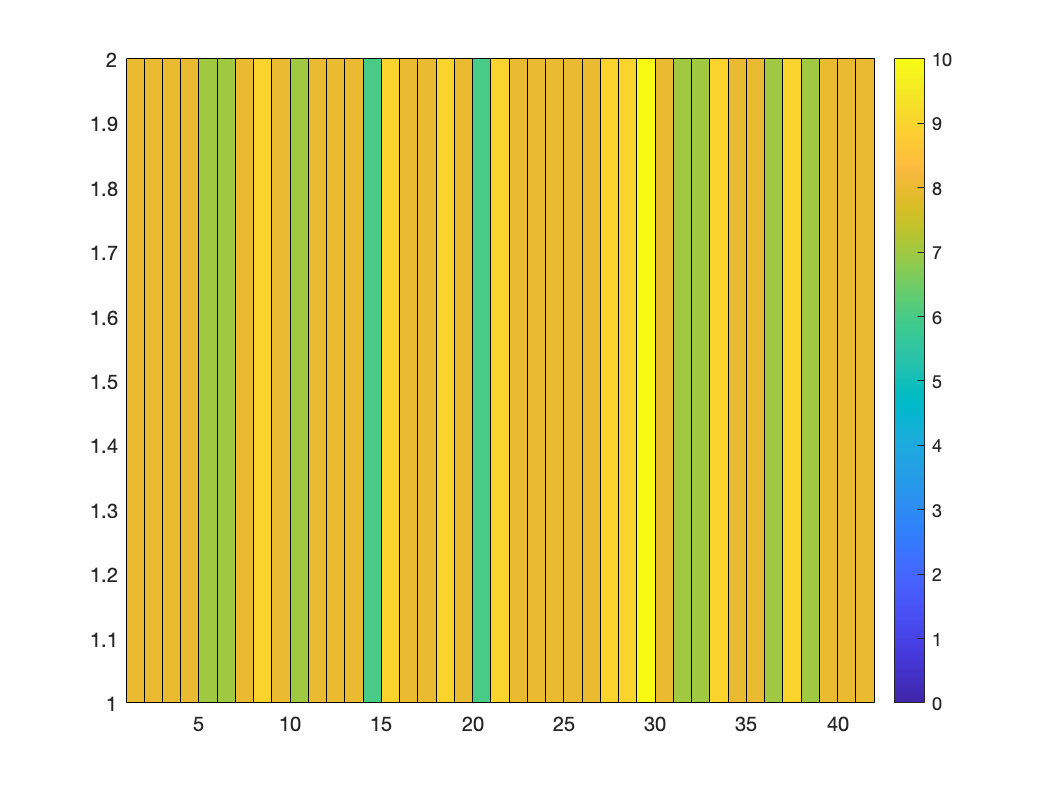

individ11 = JTrain(11, :);
emptyrow = zeros(1, 42);
pcolor([individ11 ; emptyrow])
colorbar

d) Below we will find two jokes whose ratings were strongly correlated. We will do this by first finding rho, a 42 x 42 matrix of correlation coefficients found via the corrcoef() function in MATLAB. Here the main diagonal has every entry equal to 1 (since $\rho \left(X,X\right)=\frac{\textrm{COV}\left(X,X\right)}{V\left(X\right)}=1$ ). Moreover, correlations are always bounded between 0 and 1. Since we are looking to find the highest correlations between jokes, we will set the main diagonal to be 0 in order to take those values out of consideration (since we will not be examining the correlation of a joke with itself).

rho = corrcoef(JTrain);
% maximum possible correlation is 1
for i = 1:42
    rho(i, i) = 0;
end 
colmax = max(rho);
largesttwo = maxk(colmax, 4);

We will then find which two pairs of jokes have the largest correlation and report them below.

The spherical and ball joke seem somewhat related since both require some degree of thought and sophistication. Moreover, both jokes are slightly longer (in comparison to the other 40 jokes) and seem to require more thought.

[r1,c1] = find(rho == largesttwo(1));
% joke 20 and 22 have the highest correlation 
fprintf("The 2 jokes with the highest correlation are jokes %d and %d with a correlation of %f \nThis is the %s joke which says ''%s'' \nand the %s joke which says ''%s''. \n ", r1(1), r1(2), rho(r1(1),r1(2)), char(jokes(r1(1))), char(jokeTexts(r1(1))), char(jokes(r1(2))), char(jokeTexts(r1(2))) )

The 2 jokes with the highest correlation are jokes 22 and 20 with a correlation of 0.719332 
This is the Spherical joke which says ''Milk production at a dairy farm was low, so the farmer wrote to the local university asking for help. A physicist comes to the farm for an intensive on-site investigation, and returns to the univeristy to evaluate the data. The physicist soon returns to the farm, saying to the farmer "I have the solution, but it works only in the case of spherical cows in a vacuum".'' 
and the Ball joke which says ''A mathematician, physicist, and engineer are asked to measure the volume of a red rubber ball. The mathematician measures the circumference with a string, then computes the volume. The physicist puts the ball in a beaker of water and measures the displacement. The engineer weighs the ball, then looks up the conversion formula in a Red Rubber Ball table. ''. 
 

The attorneys and positive joke do not seem to be very related however, they both incorporate some degree of thought and prior knowledge. 

Overall, it can be seen why these two pairs of jokes have larger correlation.

fprintf("\n")
[r2, c2] = find(rho == largesttwo(3));
% joke 11 and 12 have the second highest correlation 
fprintf("The 2 jokes with the second highest correlation are jokes %d and %d with a correlation of %f \nThis is the %s joke which says ''%s'' \nand the %s joke which says ''%s''. \n ", r2(1), r2(2), rho(r2(1),r2(2)), char(jokes(r2(1))), char(jokeTexts(r2(1))), char(jokes(r2(2))), char(jokeTexts(r2(2))) )

The 2 jokes with the second highest correlation are jokes 12 and 11 with a correlation of 0.646219 
This is the Attorneys joke which says ''Two attorneys went into a diner and ordered two drinks.  Then they produced  sandwiches from their briefcases and started to eat.  The owner became quite concerned and marched over and told them, "You can't eat your own sandwiches in here!"  The attorneys looked at each other, shrugged their shoulders and then exchanged sandwiches.'' 
and the Positive joke which says ''Two atoms are walking down the street when one  atom says to the other  "Oh, my! I've lost an electron!"  The second atom says"Are you sure"  The first replies "I'm positive!"''. 
 

e) Below we will now find two people whose joke ratings were strongly correlated. We will then make a scatterplot of the ratings of one person versus the ratings of the other.

In order to do this we must find the correlation coefficient matrix of the transpose of JTrain. Here ${\textrm{JTrain}}^T$ results in a 42 x 63 matrix where each individual's responses are treated as a random vector.

Then using the maxk() function, we wil find the largest two distinct correlations in the correlation coefficient matrix.

rho2 = corrcoef(JTrain');
for i = 1:63
    rho2(i, i) = 0;
end 
colmax = max(rho2);
largesttwo = maxk(colmax, 4);


[r1,c1] = find(rho2 == largesttwo(1));
% person 5 and 32 have the highest correlation 
fprintf("The 2 individuals with the highest correlated responses are person %d and %d with a correlation of %f  \n ", r1(1), r1(2), rho2(r1(1),r1(2)) )

The 2 individuals with the highest correlated responses are person 32 and 5 with a correlation of 0.721350  
 

fprintf("\n")
[r2, c2] = find(rho2 == largesttwo(3));
% person 50 and 53 have the second highest correlation 
fprintf("The 2 individuals with the second highest correlated responses are person %d and %d with a correlation of %f  \n ", r2(1), r2(2), rho2(r2(1),r2(2)) )

The 2 individuals with the second highest correlated responses are person 53 and 50 with a correlation of 0.698254  
 

The plots below show a visual graphic of the correlation between the two pairs of individuals' responses. It can be seen that both have a moderately strong positive trend which is supported by the high correlation value.

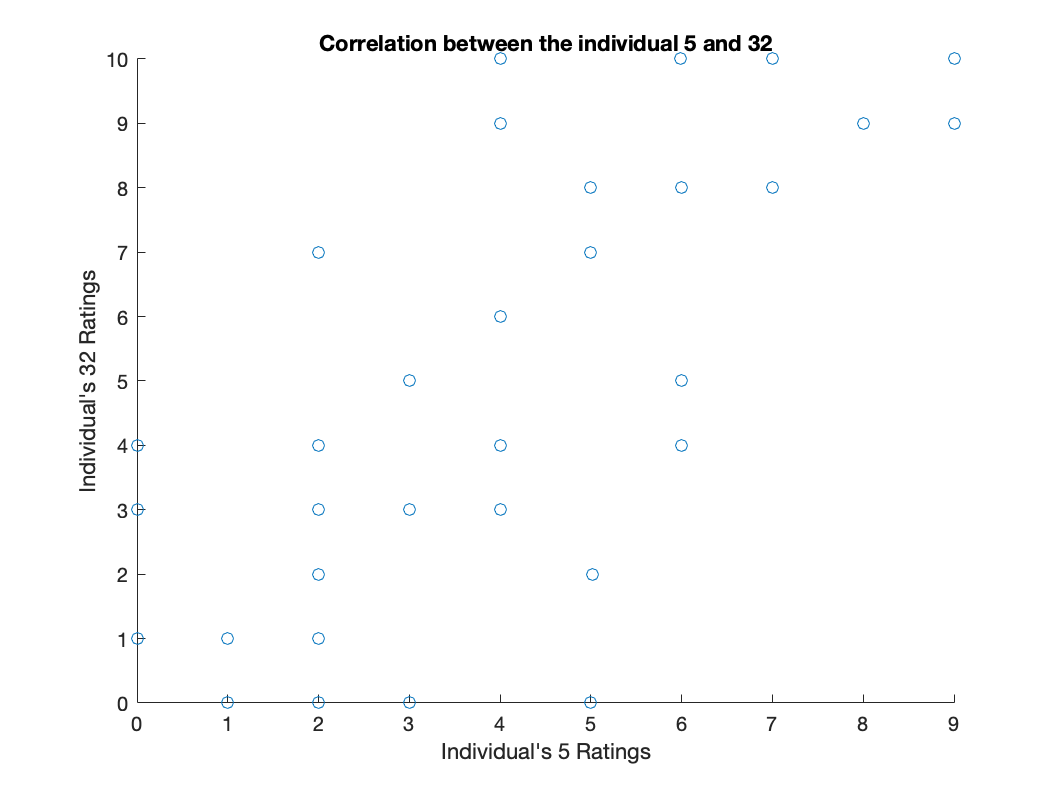


% scatterplot of individuals' 5 and 32 ratings
figure(4)
hold on 
scatter(JTrain(5,:), JTrain(32,:))
xlabel("Individual's 5 Ratings")
ylabel("Individual's 32 Ratings")
title("Correlation between the individual 5 and 32")
hold off

                    Figure 4: Scatterplot showing the largest correlation between 2 individuals

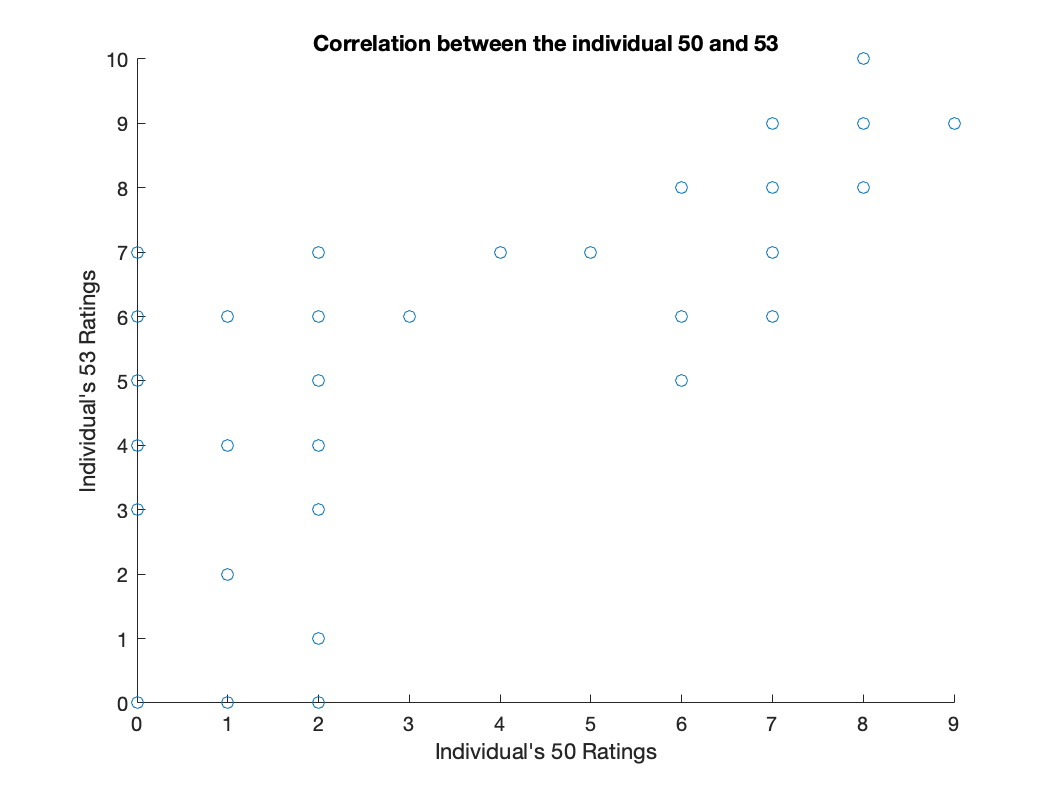

%scatterplot of individuals' 50 and 53 ratings 
figure(5)
hold on
scatter(JTrain(50,:), JTrain(53,:))
xlabel("Individual's 50 Ratings")
ylabel("Individual's 53 Ratings")
title("Correlation between the individual 50 and 53")
hold off

               Figure 5: Scatterplot showing the second argest correlation between 2 individuals

### 3. Clusters 

We have chosen to use the k means clustering method to cluster the data in JTrain. The kmeans clustering can be easily employed using the built-in function kmeans() in MATLAB. However, this function requires one to pass in the argument specifying the number of clusters (k). This is not a straightforward problem and can be found through trial and error or by observing the optimal k value, $k^*$ , using an elbow plot. 

The kmeans clustering method uses an alternating minimization technique to find both the optimal centroids (or cluster representatives) and partitions (or assignment of points to one of the k clusters). Although different notions of center and distance can be used, in this project we will solely consider euclidean distances and arithmetic means to calculate errors and centroids. Ultimately, the goal is described as follows:

#### 
$$\textrm{For}\;a\;\textrm{set}\;S=\left\lbrace x_1 \;,\ldotp \ldotp \ldotp ,x_n \right\rbrace \;\textrm{the}\;\textrm{arithmetic}\;\textrm{mean}\;\mu \;\textrm{minimizes}\;\textrm{the}\;\sum \;\textrm{of}\;\textrm{square}\;\textrm{distances}\;{\sum_{i=1}^n {||x_i -\mu ||}_2^2 }$$


Since this is impractical to solve directly, we will use the alternating minimization technique which simultaneously alternates between performing:

#### 
$$\min_{\left\lbrace S_1 \;,\ldotp \ldotp \ldotp ,S_k \right\rbrace } \sum_{i=1}^k \sum_{x\epsilon S_i } {||x_i -\mu ||}_2^2 \;\;\;\;\;\textrm{and}\;\;\;\mu_i =\frac{1}{|S_i |}\sum_{x\epsilon S_i } x\;$$
 

This is an iterative method which can be conducted via a for loop and stops when a specified tolerance or threshold is reached or once the partitions no longer minimize the error. 

Prior to clustering the data or constructing the elbow plot it is crucial to standardize the data as well as reduce the dimensionality of the data. Standardization is done via the normalize() function in MATLAB which subtracts the mean of each column from each point in that respective column and then divides each difference by its respective column standard deviation. This ensure that the JTrain data has mean equal to zero and standard deviation of 1. 

The dimensionality reduction is performed via PCA. This is important since for a fixed number of clusters (k) and dimension (d), the kmeans is solved in $\vartheta \left(n^{\textrm{dk}+1} \right)$. This clearly is a large number and grows very quickly. This becomes a particularly challenging and burdensome task when n (the number of observations) is in the thousands or millions. Below we will address this issue by reducing the data to retain only the first 2 prinicpal components. 

Although the ideal number of clusters in this scenario is 42 (since there are 42 independent jokes), this would be an unreasonably large number for k. Furthermore, we wish to see which jokes are placed in the same cluster to see if our prior investigation of correlated jokes holds. To do this we will create and analyze an elbow plot which is created by running the kmeans algorithm for different values of k and plotting the sum of distances. The hope is to find a "kink" or "elbow" in the plot where increasing the number of clusters no longer significantly decreases the sum of distances and thus marginal return is decreasing. Note that the kmeans function uses random partition initialization and centroid assingment so results will slightly differ with each execution.

Our final result are the voroi plots as seen below which uses straight line boundaries to define the clusters. The voroi plots are created by callin the makemeansplot function file (which is attached in the repository) and picture a centroid (a black large asterik) and shaded points to indicate the partition of points in one of k clusters. 

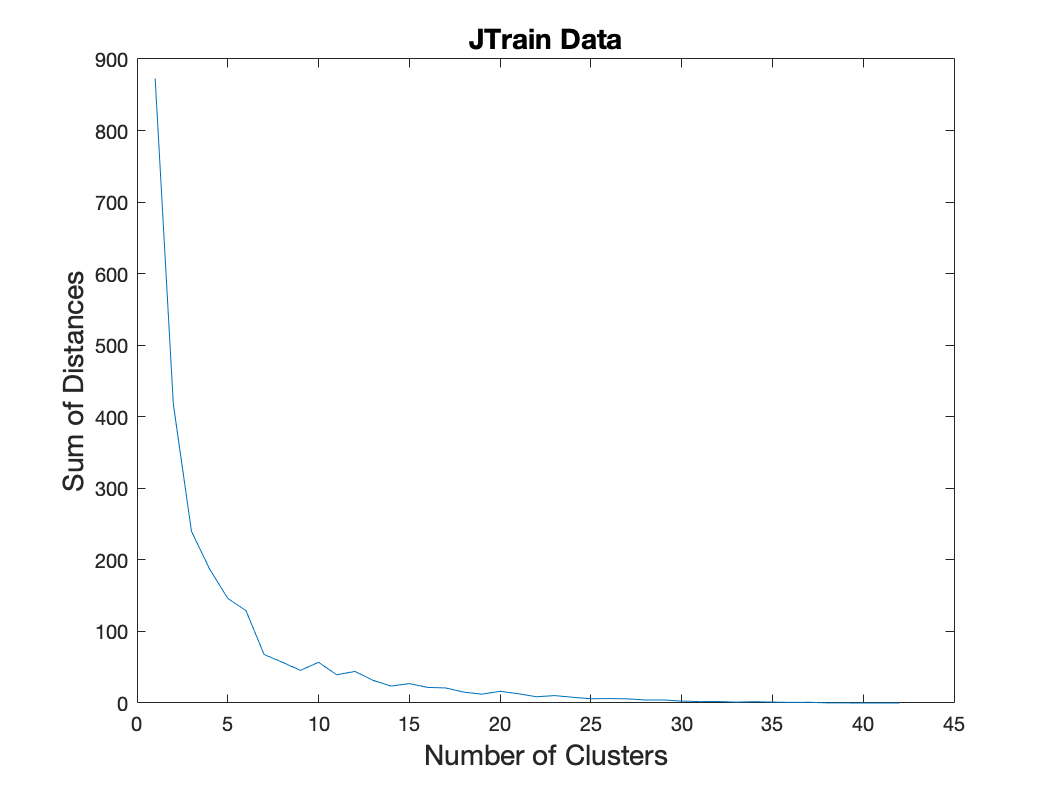


% k means clustering method

% a)Did you reduce the dimensionality of the data set first? If so, how many dimensions did you retain?
% below I am standardizing the data to have a mean of zero and standard deviation of 1
JTrainreduced = normalize(JTrain');
M = 2; % principal number of components to retain
[~,JTrainreduced] = pca(JTrainreduced,'NumComponents',M); 

% b) How many clusters did you end up using? How did you decide on this number?
% use elbow plot to choose k (optimal amount of clusters)

for k = 1:42
    %fprintf("k = %d\n", k); 
    [~,~,sumd] = kmeans(JTrainreduced,k);
    errs(k) = sum(sumd);
end 
%[idx3,C,sumdist3] = kmeans(JTrain,3)

figure(6)
plot(errs)
xlabel("Number of Clusters", 'FontSize',14); 
ylabel("Sum of Distances", 'FontSize',14); 
title("JTrain Data",'FontSize',14);  

                          Figure 6: Elbow Plot to determine the optimal number of clusters

From the visually inspecting the elbow plot, the values of k = 7 and k = 19 seem to be optimal values for the number of clusters. We will tests these by doing kmeans clustering for each of these three values and observing the error. 

the idx values below show which cluster each point was assigned to and the values of C give the x and y coordinates of each centroid.

% optimal k = 7, 19
% optimal k is observed where there is a bend / elbow in the plot

% c) Do the jokes that were clustered together seem related to you?

figure(7)
[idx,C] = kmeans(JTrainreduced, 7)

idx =      1
     7
     1
     1
     5
     4
     7
     3
     2
     1


C =     1.1110    1.0586
   -7.9768   -1.2657
   -3.6327   -1.4786
    7.4279   -2.0428
   -1.7343    2.1166
    2.7620   -2.9588
    4.9506    0.3010


f(7) = makekmeansplot(JTrainreduced, 7);

Unrecognized function or variable 'makekmeansplot'.

title("Kmeans with k = 7")

                                         Figure 7: Voroi plot for kmeans with k = 7

figure(8)
[idx,C] = kmeans(JTrainreduced, 19)
f(19) = makekmeansplot(JTrainreduced, 19);
title("Kmeans with k = 19")

                                         Figure 8: Voroi plot for kmeans with k = 19

From the plots it seems that the cluster assignments do a moderately good job of clustering similar jokes. In both kmeans clustering trials (with k = 7 and k = 19), jokes 20 and 22 were assigned to the same cluster, however, jokes 11 and 12 were assigned to different clusters. In question (e) of Part 2 (Preliminaries - Data Exploration) we found that jokes 20 and 22 had the highest pairwise correlation while jokes 11 and 12 had the second highest pairwise correlation. Thus the kmeans() algorithm is successful at detecting the largest correlation but does not detect the correlation between jokes 11 and 12. 

From a visual inspection of the voroi graphs and the cluster assignment in the idx output and further comparing these values to the joke descriptions given in "jokeTexts", I believe that kmeans clustering does a good job of grouping similar jokes based on their comedy level. Clearly this is a very individual evaluation that depends on ones sense of comedy and does not have a clear cut scale or definitive form of measurement, however, from person opinion, the clustering is decent but could be improved by increasing the number of clusters.

### 4. Predictions

In order to predict the remaining 22 scores for each of the 36 individuals in JTest we will need to employ a least squares approach. By defining X to be the first 20 columns of JTrain and Y to be the remaining 22 columns of JTrain, we can train a linear model and find the best estimated least squares coefficients. After finding these coefficients (which we will call B), we can multiple X and B to get the predicted scores of all 22 jokes for each individual. 

Formally, the least squares problem poses the following optimization:

#### 
$$\min_{B\;\epsilon R^{20\textrm{x22}} } {||Y-\textrm{XB}||}_2$$


This is performed via the normal equations given by 

#### 
$$B={\left(X^T X\right)}^{-1} X^T Y$$


However, rather than typing out the normal equations in MATLAB, it is much easier to use the backslash operator which employs a much faster and efficient alternative solution.

The predicted joke scores is stored in  36 x 22 matrix called "predictions". Here we accounted for any predicted ratings smaller than 0 or larger than 10 by adding a for loop which checks for predicted values outside of the bounds. Any extreme values are assigned to 0 or 10 depending on their value. The error is then calculated by finding the frobenius norm of the difference between the measured average joke ratings in JTrain and the predicted average joke ratings in predictions. The error given below is 1.6245 which is fairly small and proves that the linear regression method performed well on the 36 new students. 

Furthermore, figure 9 shows a plot of the predicted average joke scores versus the measured average joke scores with a line of best fit overlayed. The scatter plot shows a clear positive relationship and best fit line seems to have a slope of approximately one. This suggests that the least squares results did a very good job of predicting the joke scores given the test data.


X = JTrain(1:63, 1:20);
Y = JTrain(1:63, 21:42);
B = X\Y; %20 x 22 - each column gives the parameters for a line of best fit for one of last 22 jokes


predictions = JTest * B;
for i = 1: (36*22)
    if predictions(i) < 0
        predictions(i) = 0;
    elseif predictions(i) > 10
        predictions(i) = 10;
    end
end

% calculate error - compare to the average of the the training set for each joke is a 1x22 vector
avglastjokes = mean(Y, 1);
avgpredictions = mean(predictions, 1);
% error between average predictions - measured in frobenius norm
avgerr = norm(avglastjokes - avgpredictions, 'F')

figure(9)
scatter(avglastjokes, avgpredictions)
lsline
xlabel("Average score of the training jokes (with labeled measurements)")
ylabel("Average score of the testing jokes (unlabeled data)")
title("Comparison of predicted mean scores versus measured mean scores")

                                  Figure 9: Predicted joke scores vs observed joke scores

Finally, the panels of scatterplots shown in figure 10 show measured scores for the last 22 jokes in green and predicted scores for the 22 jokes in red. The plot suggests that the predicted values are good approximations of the observed joke evaluations. Each of the 22 subplots represents one of the jokes and with the exception of an occasional outlier point, the red and green points overlay each other and show similar spread and pattern. 

% the plot shows high correlation and frobenius error shows small error values suggesting that the scores were predicted well (in comparison with previous years)
train = JTrain(:, 21:42);
test = predictions;

figure(10)
sgtitle("Scatterplots of all the measured(green) and predicted(red) scores")
for i = 1:22
    subplot(4,6,i)
    hold on
    scatter(1:63, train(:, i), 'g')
    scatter(1:36, test(:, i), 'r')
    
    hold off
end 

                Figure 10: Scatterplots of predicted and measured joke scores for all 22 jokes

% note that in the plot above (the red values / predictions) have some
% values greater than 10

Below we will repeat the process of predicting the joke scores, however, we will preform dimensionality reduction via pca prior to finding the least squares solution. We will use the pca() function in MATLAB with the specified option of number of components set to be 2. This will reduce the independent training data set (the first 20 columns of the JTrain matrix) to the 2 most signfiicant principal components. The results are stored in a 20 x 2 array called COEFF which stores the coefficients for the two principal components and a 63 x 2 array called SCORE which stores principal component scores. 

In order to find the estimated least squares coefficients which will reduce the sum of squared errors, we will create the matrix of independent values (A) by adding a column of ones and appending the SCORE matrix with principal component scores. The matrix of dependent values will remain as trainy (the last 22 columns of JTrain). Then once again we use the backslash operator to solve the least squares problem and find the least squares coefficients. The backslash operator efficiently implements the operation below:

#### 
$$\min_{\beta } {||X\beta -Y||}_F^2 \;=\;\sum_{i=21}^{42} \min_{\beta_i } {||X\beta_i -Y_i ||}_2^2$$


Here, testy is a 36 x 22 matrix which represents the predicted joke ratings for the remaining 22 jokes. The frobenius error between the mean observed and mean predicted joke ratings is 1.3691 which is slightly better than the previous predictions. Additionally, the scatter plot of mean predicted scores versus mean observed scores shows a much better fit with much less variation. This is clearly observed by the point which closely follow the overlayed line of best fit.

Consequently, when deciding between which model to pick we would choose the second model which incorporates dimensionality reduction. Here, the pca ensures that there is less noise in the predicted values which can be seen by the reduced variation in the scatter plot and the points which follow the line of best fit more closely. Furthermore, pca avoids overfitting and ensures that the model performs well on new test data as well as the training data which was used to train the model. Each column of testy corresponds to the coefficients of a least squares equation which would be used to predict rating scores for the respective joke. Thus, when deciding between models I would use testy(:,i) as the best linear model to predict the rating of joke i.

trainx = JTrain(1:63, 1:20);
trainy = JTrain(1:63, 21:42);

testx = JTest;
% reducing the dimension via pca reduces the noise in the predictions
[COEFF,SCORE] = pca(trainx,'numComponents',2);

SCORE_test = (testx - mean(trainx))*COEFF; 
A = [ones(size(SCORE,1),1) , SCORE];
B = trainy;
C = A\B; % least squares matrix of coefficients -- size 3 x 22
testy = C(1,:) + (testx - mean(trainx))*COEFF * C(2:end, :);  


for i = 1:(36*22)
    if testy(i) < 0
        testy(i) = 0;
    elseif testy(i) > 10
        testy(i) = 10;
    end
end
% 
% calculate error - compare to the average of the the training set for each joke is a 1x22 vector
avgtraining = mean(trainy, 1);
avgtesting = mean(testy, 1);
% error between average predictions - measured in frobenius norm
avgerr = norm(avgtraining - avgtesting, 'F')
figure(11)
scatter(avgtraining, avgtesting)
lsline
xlabel("Average score of the reduced training jokes (with labeled measurements)")
ylabel("Average score of the testing jokes (unlabeled data)")
title("Comparison of predicted mean scores versus measured mean scores after dimensionality reduction")

### 5. Conclusion

In sections 1-4 above, we have successfully analyzed the observational joke data, identified correlated variables and observations, clustered predictors, and estimated predicted values. This was all done with the underlying approaches of linear algebra, dimensionality reduction, and the notion of covariance. Our discussions indicated which methods we thought performed the best. Reducing the dimensions seemed to work the best for predictions. 